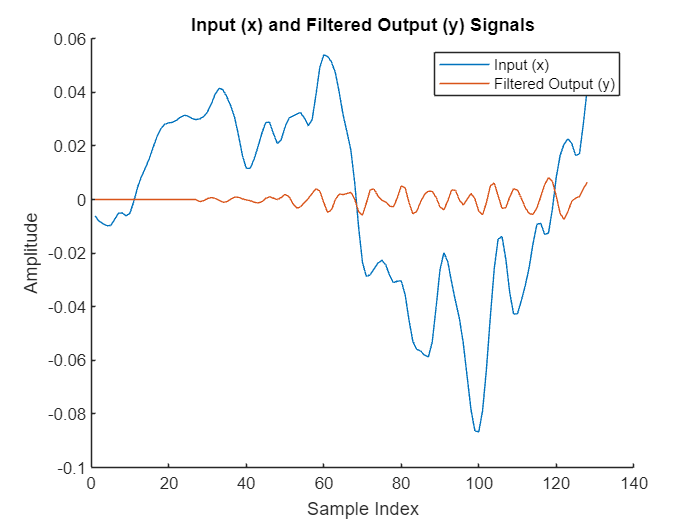

% INITIALIZE PARAMETERS
M = 26;                         % M-tap filter (Filter order)
N_FFT = 128;                    % Number of samples for FFT (Frequency resolution)

%% READ INPUT SIGNAL
filename = 'guitar.wav';
[x, fs] = audioread(filename);   % Read audio file (x: signal, fs: sampling frequency)
x = x(1:3*fs);                  % Select the first 3 seconds of audio
N = length(x);                  % Number of samples in the signal
y = zeros(N, 1);                 % Initialize output signal with zeros

%% DESIGNING A FIR FILTER (HIGH-PASS)
a = fir1(M, 10000/fs, 'high')'; % Design a high-pass FIR filter
fvtool(a, 1);                    % Visualize frequency response of the filter
M = length(a);                    % Update M to reflect the actual filter length

%% PROCESSING OF INPUT SIGNAL (CONVOLUTION)
% Uncomment the following line to use a moving average filter instead:
% a = ones(M, 1) / M;            

for i = (M+1):N                   % Loop over input samples, starting after the filter delay
    vect = i - (M-1) : i;       % Get the current window of samples to process
    y(i) = sum(x(vect) .* a);    % Calculate the filtered output by convolving with 'a'
end

% Calculate FFT magnitudes for plotting
mag_fft_x = abs(fft(x(1:N_FFT)));
mag_fft_y = abs(fft(y(1:N_FFT)));

%% DISPLAY RESULTS

% Time-domain plot of input and output signals
figure;
hold on; 
plot(x(1:N_FFT));  
plot(y(1:N_FFT));
xlabel('Sample Index');
ylabel('Amplitude');
title('Input (x) and Filtered Output (y) Signals');
legend("Input (x)", "Filtered Output (y)");

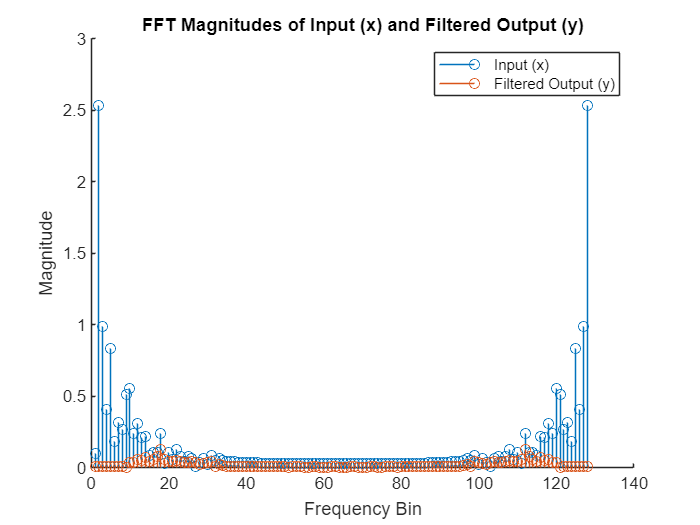


% Frequency-domain plot of FFT magnitudes
figure;
hold on; 
stem(mag_fft_x); 
stem(mag_fft_y);
xlabel('Frequency Bin');
ylabel('Magnitude');
title('FFT Magnitudes of Input (x) and Filtered Output (y)');
legend("Input (x)", "Filtered Output (y)");


%% PLAY OUTPUT SIGNAL
sound(y, fs); 